# Discrete Fourier Transform (DFT)

## DFT


$$X\, =\, S^Hx$$



$$X[k]\, =\, \langle x,s_k\rangle\, =\, \sum \limits_{k=0}^{N-1} X[k]\,\frac{e^{-j\frac{2 \pi}{N}kn}}{\sqrt{N}}$$


## inverse DFT


$$x\, =\, SX$$



$$x[n]\, =\, \sum \limits_{k=0}^{N-1}X[k]\, \frac{e^{j\frac{2 \pi}{N}kn}}{\sqrt{N}}$$


FFT algorithms are so commonly employed to compute DFTs that the term 'FFT' is often used to mean 'DFT': DFT refers to a mathematical transformation or function, whereas 'FFT' refers to a specific family of algorithms for computing DFTs.

- use fft command to compute dft

- fft (computationally efficient)

But why are you using fft ?

%
Fe=100;
Fmax=Fe/2;
Nres=100;
Npts=50;
 
f=0:Nres/Fe:Fmax;
Yc=zeros(1,length(f));
Ys=zeros(1,length(f));
t=0:1/Fe:Npts;
y=cos(t*pi/2);
%comparaison  DFT Vs FFT
tic;
for fi=1:length(f)
    Yc(1,fi)=y*cos(-2*pi*f(1,fi)*t'/(Npts)); 
   Ys(1,fi)=y*sin(-2*pi*f(1,fi)*t'/(Npts)); 
   %Ye(1,fi)=y*exp(-2*pi*j*f(1,fi)*t'/(Npts)); 
end
 YFI=Yc+i*Ys;
%YFI=Ye
 toc;

Elapsed time is 0.589491 seconds.


 
 tic;Uc=fft(y);toc;

Elapsed time is 0.000558 seconds.


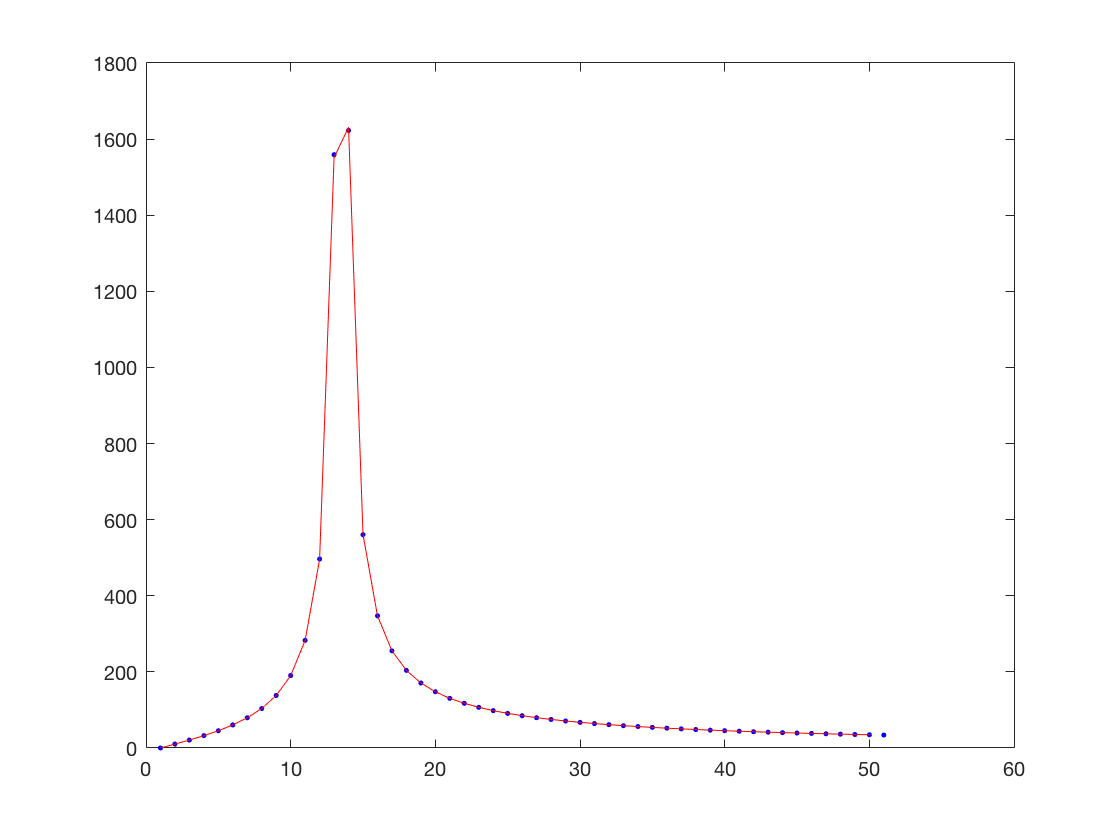

 
 figure;
 plot(abs(YFI),'b.');
 hold on;
 U=abs(fft(y));
 plot(U(1:50),'r');

- Circular convolution in the time domain = multiplication in the frequency domain


$$Y[k]=H[k]X[k]$$



$$h[n]\star x[n]$$
 
$$\longleftrightarrow$$
 
$$H[k]X[k]$$



$$y[n]=\text{IDFT}(Y[k])$$
